## Nanjing lab strains


clc;
clear;
% load ./data/alldata_withlabstrain.mat;
% save('./data/data/seq_plus.mat','seq_plus');
load ./data/data/seq_plus.mat;

load ./data/labproximitynum.mat;

proximity_recnum={lab.selfrecnum}';
proximity_recnum_nj=proximity_recnum([74,76:118]);%Errors in genome sequencing of P8 and sid60

seq_plus_NJ.strain_name=seq_plus.strain_name([74,76:118]);
seq_plus_NJ.rec_seq=seq_plus.rec_seq([74,76:118]);
seq_plus_NJ.PepAmotif45 =seq_plus.PepAmotif45([74,76:118]);

NJ=struct();
for i=1:length(seq_plus_NJ.strain_name)
    NJ(i).strain_name=seq_plus_NJ.strain_name{i};
    NJ(i).PepAmotif45=seq_plus_NJ.PepAmotif45{i};
    temp=proximity_recnum_nj{i};
    NJ(i).proxirecnum=temp;
    if ~isempty(temp)
        NJ(i).proxrec=seq_plus_NJ.rec_seq(i).seq{temp};   
    end
    temp_1=seq_plus_NJ.rec_seq(i).seq;
    num=1:length(temp_1);
    a=ismember(num,temp);
    b=find(a==0);
    temp_2=temp_1(b);
    NJ(i).cheatrec=temp_2';   
end


## Sequence distance between self-rec of nanjing lab strains

proxirec_seqdist44=zeros(length(NJ),length(NJ));
if ~exist('./output/proxirec_seqdist44.mat','file')
    for i=1:length(NJ)
        for j = (i+1):length(NJ)
            proxirec_seqdist44(i,j)=seqpdist({NJ(i).proxrec;NJ(j).proxrec}, 'method', 'p-distance', 'PairwiseAlignment', true,'Alphabet','AA');
            proxirec_seqdist44(j,i)=proxirec_seqdist44(i,j);
        end
    end
    save('./output/proxirec_seqdist44.mat','proxirec_seqdist44');
else
    load('./output/proxirec_seqdist44.mat');
end


dist_trehs=0.3;
disttrehs=dist_trehs;
distm_rec=proxirec_seqdist44;
linkm_rec=linkage(distm_rec);
optleaf_rec = optimalleaforder(linkm_rec,distm_rec);
[recgroup,totalgnum,leaforder_alonesp] = Cluster_byconnection(distm_rec,disttrehs,optleaf_rec);
toplotm=distm_rec(leaforder_alonesp,leaforder_alonesp);



## Sequence distance between experimental strains PepA45

seqdist_zd_PepA45=zeros(length(NJ),length(NJ));
if ~exist('./output/seqdist_zd_PepA45.mat','file')
    for i=1:length(NJ)
        for j = (i+1):length(NJ)
            seqdist_zd_PepA45(i,j)=pdist_zd({NJ(i).PepAmotif45;NJ(j).PepAmotif45}, 10, 10);
            seqdist_zd_PepA45(j,i)=seqdist_zd_PepA45(i,j);
        end
    end
    save('./output/seqdist_zd_PepA45.mat','seqdist_zd_PepA45');
else
    load('./output/seqdist_zd_PepA45.mat');
end

dist_trehs=0.1;
disttrehs=dist_trehs;
distm_rec=seqdist_zd_PepA45;
linkm_rec=linkage(distm_rec);
optleaf_rec = optimalleaforder(linkm_rec,distm_rec);
[recgroup,totalgnum,leaforder_alonesp] = Cluster_byconnection(distm_rec,disttrehs,optleaf_rec);
toplotm=distm_rec(leaforder_alonesp,leaforder_alonesp);


## rec for all Nanjing lab strains


load ./data/location.mat;%Add non-producers
without_syn_NJ={without_syn.spname}';
without_syn_NJ=without_syn_NJ(7:17);
load ./data/fpva_fs.mat;
NJ_sp=fpva_fs([369,371:500,503:end]);
a=unique({NJ_sp.spname});
%There are 7 strains that have no syn or rec at all, and indeed no pyo system.
a=ismember(without_syn_NJ,{NJ_sp.spname});
%There are 4 strains of bacteria that do not have syn but have rec, no selfrec, and Cheater.
b=find(a==1);
sp4name=without_syn_NJ(b)

sp4name = 4×1 cell 数组
    {'Sid19'}
    {'sid13'}
    {'sid2' }
    {'sid7' }


temp={NJ_sp.spname}';
a=ismember(temp,sp4name);
b=temp(a);

temp_seq={NJ_sp.fsseq}';
c=temp_seq(a);


a=ismember({fpva_fs.spname},[{NJ.strain_name}]);
NJ_spname={fpva_fs.spname}';
NJ_spname=NJ_spname(a);
NJ_fsseq={fpva_fs.fsseq}';
NJ_fsseq=NJ_fsseq(a);

%加上4个cheater
NJ_spname=[NJ_spname;b];
NJ_fsseq=[NJ_fsseq;c];

[i,j]=unique(NJ_spname,'first');

temp_name=NJ_spname(sort(j));


allrec_seqdist_48=zeros(length(NJ_spname),length(NJ_spname));
if ~exist('./output/allrec_seqdist_withcheater_48.mat','file')
    for i=1:length(NJ_spname)
        for j = (i+1):length(NJ_spname)
            allrec_seqdist_48(i,j)=seqpdist({NJ_fsseq{i};NJ_fsseq{j}}, 'method', 'p-distance', 'PairwiseAlignment', true,'Alphabet','AA');
            allrec_seqdist_48(j,i)=allrec_seqdist_48(i,j);
        end
    end
    save('./output/allrec_seqdist_withcheater_48.mat','allrec_seqdist_48');
else
    load('./output/allrec_seqdist_withcheater_48.mat');
end


if ~exist('./output/cluster_lab_withcheater_48.mat','file')
    dist_trehs=0.3;
    disttrehs=dist_trehs;
    distm_rec=allrec_seqdist_48;
    
    linkm_rec=linkage(distm_rec);
    optleaf_rec = optimalleaforder(linkm_rec,distm_rec);
    [recgroup,totalgnum,leaforder_alonesp] = Cluster_byconnection(distm_rec,disttrehs,optleaf_rec);
    save('./output/cluster_lab_withcheater_48.mat','linkm_rec','leaforder_alonesp',"totalgnum","recgroup",'optleaf_rec');
else
    load('./output/cluster_lab_withcheater_48.mat')
end

## Based on whether the receiver strain has a receptor in the same group as the donor strain self-receptor, predict whether the pyo of the donor strain can be utilized by the receiver

for i=1:length(temp_name)
    name1=temp_name{i};
    a=ismember(NJ_spname,name1);
    b=find(a==1);
    temprecgnum=recgroup(b);
    NJ(i).spname2=name1;
    NJ(i).cheatgnum=temprecgnum;
    if i<45
        num=NJ(i).proxirecnum;
        c=b(num);
        NJ(i).proxignum=recgroup(c);
    end
end

predict_inter=zeros(length(temp_name),size(seqdist_zd_PepA45,1));
for i=1:size(seqdist_zd_PepA45,1)
    gnum=NJ(i).proxignum;
    for j=1:length(temp_name)
        a=ismember(NJ(j).cheatgnum,gnum);
        b=find(a==1);
        if ~isempty(b)
            predict_inter(j,i)=1;
        else
            predict_inter(j,i)=0;
        end
    end
end

## UZH lab strains

sp24=readtable('./data/strain_name.xlsx');
Rolf84=readtable('./data/useRolfstrain_tableS2.xlsx');

Rolf84_struct=table2struct(Rolf84);
for i=1:size(Rolf84,1)
    name1=Rolf84.donorID{i};
    a=find(ismember(sp24.name,name1));
    if ~isempty(a)
        Rolf84_struct(i).sp_name=sp24.strains{a};
    else
        Rolf84_struct(i).sp_name= Rolf84_struct(i).donorID;
    end
end
lab_R={lab.spname};
lab_R=lab_R(1:73);
lab_R_1=struct();
for i=1:length(lab_R)
    lab_R_1(i).len=length(lab_R{i});
    if i<55
        if lab_R_1(i).len<13
            temp=lab_R{i};
            lab_R_1(i).spname=temp(8:end);
        elseif lab_R_1(i).len==15
            lab_R_1(i).spname=temp(8:10);
        elseif lab_R_1(i).len>15
            temp=lab_R{i};
            lab_R_1(i).spname=temp(14:end);
        end

    else
        lab_R_1(i).spname=lab_R{i};
    end         
end



Rolf=struct();
num=0

num = 0

for i=1:size(Rolf84_struct,1)
    name1=Rolf84_struct(i).sp_name;
    a=find(ismember({lab_R_1.spname},name1));
    b=find(contains({without_syn.spname},name1));
    c=find(contains(unuseapname,name1));
    if ~isempty(a)
        Rolf84_struct(i).selfrecnum=lab(a).selfrecnum;
        if ~isempty(Rolf84_struct(i).selfrecnum) && length(Rolf84_struct(i).selfrecnum)<2
            num=num+1;
            Rolf(num).spname=lab(a).spname;
            Rolf(num).spname1=Rolf84_struct(i).sp_name;
            Rolf(num).spname2=Rolf84_struct(i).donorID;
            
            Rolf(num).donor1=Rolf84_struct(i).donorID;
            Rolf(num).receiver1=Rolf84_struct(i).receiverID;
            Rolf(num).PVDE1=Rolf84_struct(i).estimate;
            Rolf(num).p1=Rolf84_struct(i).significant;
            Rolf(num).donor2=Rolf84_struct(i).donorID_1;
            Rolf(num).receiver2=Rolf84_struct(i).receiverID_1;
            Rolf(num).PVDE2=Rolf84_struct(i).estimate_1;
            Rolf(num).p2=Rolf84_struct(i).significant_1;
            Rolf(num).selfrecnum=Rolf84_struct(i).selfrecnum;
            
        end
   elseif ~isempty(b)
        Rolf84_struct(i).selfrecnum=100;%完全cheater
    elseif ~isempty(c)
        Rolf84_struct(i).selfrecnum=50;%可能cheater    
    end
end

pao1FpvA_featureseq=fastaread('./data/Pao1_featureseq.fasta');%feature sequence
for i=1:length(Rolf)
    name1=Rolf(i).spname;
    a=find(ismember(seq_plus.strain_name,name1));
    Rolf(i).PepAmotif45=seq_plus.PepAmotif45{a};
    temp=Rolf(i).selfrecnum;
    Rolf(i).proxirecnum=temp;
    if ~isempty(temp)
        Rolf(i).proxrec=seq_plus.rec_seq(a).seq{1,temp};   
    end
    temp_1=seq_plus.rec_seq(a).seq;
    num=1:length(temp_1);
    b=ismember(num,temp);
    c=find(b==0);
    temp_2=temp_1(c);
    Rolf(i).cheatrec=temp_2';   
end
num=length(Rolf)+1;
Rolf(num).spname=pao1FpvA_featureseq.Header;
Rolf(num).proxrec=pao1FpvA_featureseq.Sequence;
Rolf(num).proxirecnum=1;

## Sequence distance between self-rec of UZH lab strains

proxirec_seqdist33=zeros(length(Rolf),length(Rolf));
if ~exist('./output/proxirec_seqdist33.mat','file')
    for i=1:length(Rolf)
        for j = (i+1):length(Rolf)
            proxirec_seqdist33(i,j)=seqpdist({Rolf(i).proxrec;Rolf(j).proxrec}, 'method', 'p-distance', 'PairwiseAlignment', true,'Alphabet','AA');
            proxirec_seqdist33(j,i)=proxirec_seqdist33(i,j);
        end
    end
    save('./output/proxirec_seqdist33.mat','proxirec_seqdist33');
else
    load('./output/proxirec_seqdist33.mat');
end


dist_trehs=0.3;
disttrehs=dist_trehs;
distm_rec=proxirec_seqdist33;
linkm_rec=linkage(distm_rec);
optleaf_rec = optimalleaforder(linkm_rec,distm_rec);
[recgroup,totalgnum,leaforder_alonesp] = Cluster_byconnection(distm_rec,disttrehs,optleaf_rec);
toplotm=distm_rec(leaforder_alonesp,leaforder_alonesp);



## All rec of UZH lab strains

a=ismember({fpva_fs.spname},{Rolf.spname});
Rolf_spname={fpva_fs.spname}';
Rolf_spname=Rolf_spname(a);
Rolf_fsseq={fpva_fs.fsseq}';
Rolf_fsseq=Rolf_fsseq(a);

%plus pathogen pao1 strains
Rolf_spname=[Rolf_spname;Rolf(end).spname];
Rolf_fsseq=[Rolf_fsseq;Rolf(end).proxrec];
order=zeros(length(Rolf_spname),1);
num=0;
for i=1:length(Rolf)
    name1=Rolf(i).spname;
    a=find(ismember(Rolf_spname,name1));
    for j=1:length(a)
        num=num+1;
        order(num,1)=a(j);
    end
end
Rolf_spname_order=Rolf_spname(order);
Rolf_fsseq_order=Rolf_fsseq(order);

allrec_seqdist_33=zeros(length(Rolf_spname_order),length(Rolf_spname_order));
if ~exist('./output/allrec_seqdist_33.mat','file')
    for i=1:length(Rolf_spname_order)
        for j = (i+1):length(Rolf_spname_order)
            allrec_seqdist_33(i,j)=seqpdist({Rolf_fsseq_order{i};Rolf_fsseq_order{j}}, 'method', 'p-distance', 'PairwiseAlignment', true,'Alphabet','AA');
            allrec_seqdist_33(j,i)=allrec_seqdist_33(i,j);
        end
    end
    save('./output/allrec_seqdist_33.mat','allrec_seqdist_33');
else
    load('./output/allrec_seqdist_33.mat');
end


if ~exist('./output/cluster_Rolf_33.mat','file')
    dist_trehs=0.3;
    disttrehs=dist_trehs;
    distm_rec=allrec_seqdist_33;
    
    linkm_rec=linkage(distm_rec);
    optleaf_rec = optimalleaforder(linkm_rec,distm_rec);
    [recgroup,totalgnum,leaforder_alonesp] = Cluster_byconnection(distm_rec,disttrehs,optleaf_rec);
    save('./output/cluster_Rolf_33.mat','linkm_rec','leaforder_alonesp',"totalgnum","recgroup",'optleaf_rec');
else
    load('./output/cluster_Rolf_33.mat')
end


## Based on whether the receiver strain has a receptor in the same group as the donor strain self-receptor, predict whether the pyo of the donor strain can be utilized by the receiver

for i=1:length(Rolf)
    name1=Rolf(i).spname;
    a=ismember(Rolf_spname_order,name1);
    b=find(a==1);
    temprecgnum=recgroup(b);
    Rolf(i).spnamenew=name1;
    Rolf(i).cheatgnum=temprecgnum;
    
    num=Rolf(i).proxirecnum;
    c=b(num);
    Rolf(i).proxignum=recgroup(c);

end

## Assign the rec of the experimental strain to the lock-key groups of the database


load ./data/data/recgroup.mat;
load ./data/data/rec_infor.mat;
load ./data/data/rec_seqdist_1.mat;
load ./data/data/rec_seqdist_2.mat;

rec1928.seqdist678910=[rec_seqdist_1;rec_seqdist_2];
rec1928.strainname=rec1989.strainname;

sidnum=readtable('./data/sidnum.xlsx');
roupsize=zeros(1,totalgnum);
group_typebelong=zeros(4,totalgnum);
node_groupid=recgroup;
changedleaforder_bygroups=leaforder_alonesp;
for g=1:totalgnum
    members_rec=find(node_groupid==g);
    members_straintype=rec1989.sptypeid(members_rec);
    group_typebelong(:,g)=[sum(members_straintype==1),sum(members_straintype==2),sum(members_straintype==3),sum(members_straintype==4)];
    thisg_members=find(node_groupid(changedleaforder_bygroups)==g);
    groupsize(g)=length(thisg_members);
end

[value,order]=sort(groupsize,'descend');
a=find(group_typebelong(1,:)~=0);
b=find(group_typebelong(2,:)~=0);
c=union(b,a);

## database data


aa=ismember(recgroup,c);
recgroup_use=recgroup(aa);
FpvA_use=rec1989.seq(aa);
FpvA_use_seqdist=rec1928.seqdist678910(aa,aa);
FpvA_use_spname=rec1928.strainname(aa);
[value1,order1]=sort(recgroup_use);
recgroup_use_order=recgroup_use(order1);
FpvA_use_order=FpvA_use(order1);
FpvA_use_seqdist_order=FpvA_use_seqdist(order1,order1);
FpvA_use_spname_order=FpvA_use_spname(order1);

## Experimental strain data (change selfrec to all rec on the original basis)

%experimental data
pyoe=readtable('./data/PYOE-nm_method.xlsx');
orderinpredict_y=zeros(size(pyoe,1),1);
for i=1:size(pyoe,1)
    name1=pyoe.sidE{i};
    orderinpredict_y(i,1)=find(ismember(lower(temp_name),lower(name1)));
end

a=ismember(lower(pyoe.sidE),lower(sp4name));
b=find(a==0);
orderinpredict_x=orderinpredict_y(b);
predict_donor_name=temp_name(orderinpredict_x);
predict_recevier_name=temp_name(orderinpredict_y);

predict_inter24_order=predict_inter(orderinpredict_y,orderinpredict_x);

temp_gsh={NJ.spname2}';
a=ismember(temp_gsh,predict_donor_name);
NJ_expstrian_name_self=temp_gsh(a);
temp_seq={NJ.proxrec}';
NJ_expstrian_seq_self=temp_seq(a);

temp_gsh={NJ_sp.spname}';
a=ismember(temp_gsh,predict_recevier_name);
NJ_expstrian_name_all=temp_gsh(a);
temp_seq={NJ_sp.fsseq}';
NJ_expstrian_seq_all=temp_seq(a);

%Rolf
Rolf_expstrian_name_self={Rolf.spname}';
Rolf_expstrian_seq_self={Rolf.proxrec}';

Rolf_expstrian_name_all=Rolf_spname_order;
Rolf_expstrian_seq_all=Rolf_fsseq_order;

allexpstrain_name=[NJ_expstrian_name_all;Rolf_expstrian_name_all];
allexpstrain_seq=[NJ_expstrian_seq_all;Rolf_expstrian_seq_all];

selfexpstrain_name=[NJ_expstrian_name_self;Rolf_expstrian_name_self];
selfexpstrain_seq=[NJ_expstrian_seq_self;Rolf_expstrian_seq_self];

## allrec

if ~exist('./output/seqdist_all_1.mat','file')
    seqdist_all=zeros(160,4367);
    for i=1:160
        for j=1:4367
            seqdist_all(i,j)=seqpdist({allexpstrain_seq{i},FpvA_use_order{j}}, 'method', 'p-distance', 'PairwiseAlignment', true);
        end
    end
    save('./output/seqdist_all_1.mat','seqdist_all');
else
    load('./output/seqdist_all_1.mat');
end

recgroup_all=zeros(160,1);
for i=1:160
    a=find(seqdist_all(i,:)<=0.3);
    recg_temp=unique(recgroup_use_order(a));
    if ~isempty(recg_temp)
        recgroup_all(i,1)=recg_temp;
    end
    
end

%%

## selfrec

if ~exist('./output/seqdist_self.mat','file')
    seqdist_self=zeros(53,4367);
    for i=1:53
        for j=1:4367
            seqdist_self(i,j)=seqpdist({selfexpstrain_seq{i},FpvA_use_order{j}}, 'method', 'p-distance', 'PairwiseAlignment', true);
        end
    end
    save('./output/seqdist_self.mat','seqdist_self');
else
    load('./output/seqdist_self.mat');
end

recgroup_self=zeros(53,1);
for i=1:53
    a=find(seqdist_self(i,:)<=0.3);
    recg_temp=unique(recgroup_use_order(a));
    recgroup_self(i,1)=recg_temp;
end


## Figure S5 

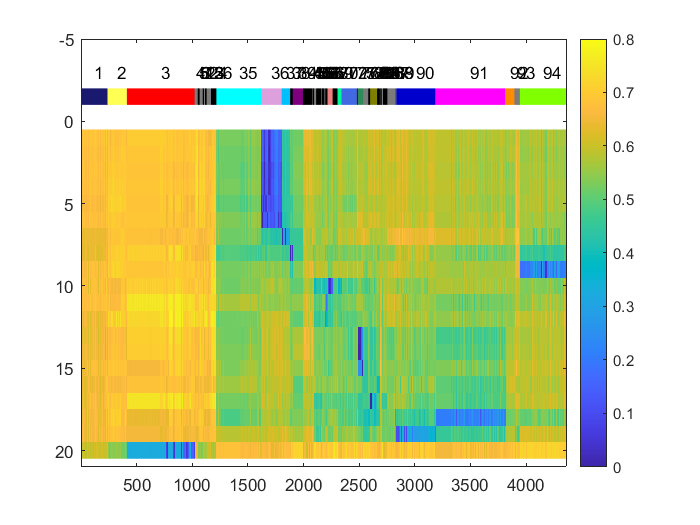

% NJ_expstrian_name_self
if ~exist('./output/seqdist_self_20.mat','file')
    seqdist_self_20=zeros(20,20);
    for i=1:20
        for j=1:20
            seqdist_self_20(i,j)=seqpdist({NJ_expstrian_seq_self{i},NJ_expstrian_seq_self{j}}, 'method', 'p-distance', 'PairwiseAlignment', true);
        end
    end
    save('./output/seqdist_self_20.mat','seqdist_self_20');
else
    load('./output/seqdist_self_20.mat');
end

dist_trehs=0.3;
disttrehs=dist_trehs;
distm_rec_20=seqdist_self_20;
linkm_rec_20=linkage(distm_rec_20);
optleaf_rec_20 = optimalleaforder(linkm_rec_20,distm_rec_20);
[recgroup_20,totalgnum_20,leaforder_alonesp_20] = Cluster_byconnection(distm_rec_20,disttrehs,optleaf_rec_20);
recgroup_self_20=recgroup_self(1:20);
recgroup_self_20_order=recgroup_self_20(leaforder_alonesp_20);
NJ_expstrian_name_self_order=NJ_expstrian_name_self(leaforder_alonesp_20);

%Receptor
figure;
recseqdist_last=seqdist_self(1:20,:);
recseqdist_last=recseqdist_last(leaforder_alonesp_20,:);
imagesc(recseqdist_last);
colorbar
caxis([0 0.8])
hold on;




colorgroups_1=readtable('./data/colorcode17.xlsx');
colorgroups=colorgroups_1(:,3:5);
colorgroups=table2array(colorgroups);
uniquerecg=unique(recgroup_use_order);
for i=1:length(uniquerecg)
        g=uniquerecg(i);
        b=find(colorgroups_1.Rec_groupid==g);
        thisg_members=find(recgroup_use_order==g);
        if ~isempty(b)
            colorcode=colorgroups(b,:);
        elseif mod(i,2)==1
            colorcode=[0 0 0];
        else
            colorcode=[123/255,123/255,123/255];
        end
        text( mean(thisg_members),-3,num2str(g));
        ph1=patch([thisg_members(1)-1,thisg_members(1)-1,thisg_members(end),thisg_members(end)],[-2,-1,-1,-2],colorcode);
        ph1.LineStyle='none';
       
                      
end
ylim([-5,size(recseqdist_last,1)+1]);

## Figure S6

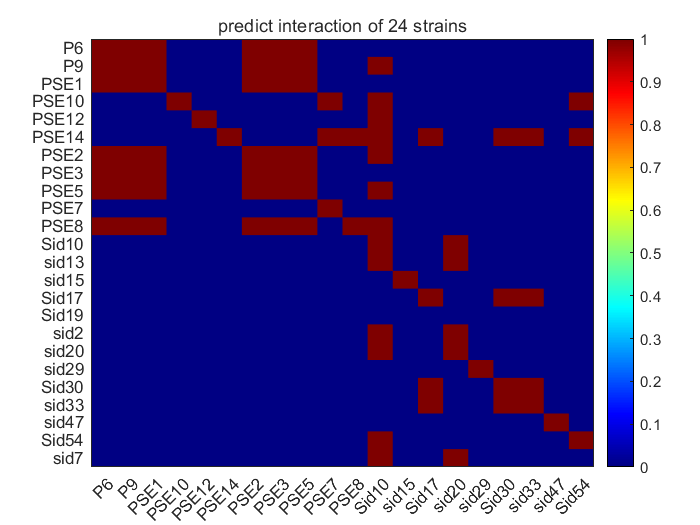

%Predicted interaction results of 24 bacterial strains
figure;
h=heatmap(predict_donor_name,predict_recevier_name,predict_inter24_order,'GridVisible','off');
title('predict interaction of 24 strains')
h.Colormap = jet;
h.CellLabelColor = 'none';
h.FontName = 'Arial';
colorbar

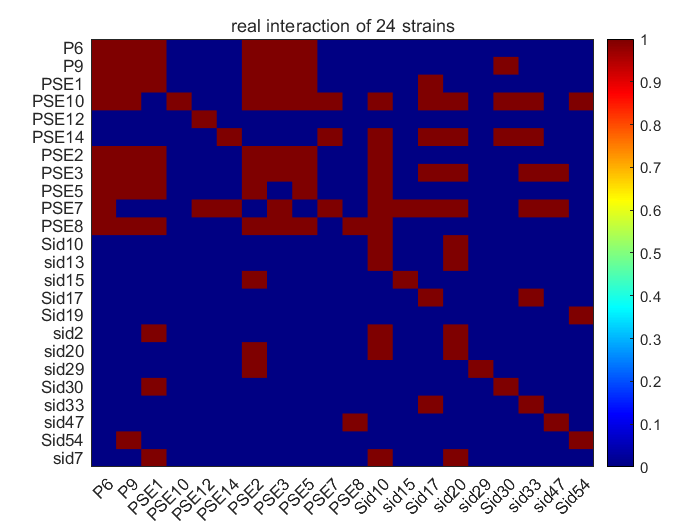

%Real experimental interaction results
pyoe_1=table2array(pyoe(1:24,2:21));
pyoe_1(pyoe_1>=0.05)=1;
pyoe_1(pyoe_1<0.05)=0;
figure;
h=heatmap(predict_donor_name,predict_recevier_name,pyoe_1,'GridVisible','off');
%caxis([-0.5 0.5])
title('real interaction of 24 strains')
h.Colormap = jet;
h.CellLabelColor = 'none';
h.FontName = 'Arial';
colorbar


%Calculate accuracy
num=0;
for i=1:24
    for j=1:20
        if pyoe_1(i,j)==predict_inter24_order(i,j)
            num=num+1;
        end
    end
end

accuracy1=num/(20*24)

accuracy1 = 0.9042

## Figure2e

%network_NJ
num=0;
network_NJ=[];
for i=1:20
    for j=1:24
        num=num+1;
        network_NJ(num).producer=predict_donor_name{i};
        network_NJ(num).source=['pyo-',num2str(recgroup_self_20(i))];
        network_NJ(num).target=predict_recevier_name{j};
        network_NJ(num).isproducer= 0;
        network_NJ(num).edgesize= 1;
        b=find(colorgroups_1.Rec_groupid==recgroup_self_20(i));
        if ~isempty(b)
            color_1=colorgroups_1.Hex{b};
        else
            color_1="#BFBFBF";
        end
        network_NJ(num).edgecolor= color_1;
        network_NJ(num).predict= predict_inter24_order(j,i);
        network_NJ(num).real01= pyoe_1(j,i);
        network_NJ(num).wrong = [num2str(predict_inter24_order(j,i)),'-',num2str( pyoe_1(j,i))];
        
    end
end

sp_11=unique({network_NJ.producer}');
for i=1:20
    
        network_NJ(480+i).source=sp_11{i};
        network_NJ(480+i).target=['pyo-',num2str(recgroup_self_20(i))];
        network_NJ(480+i).isproducer= 1;
        network_NJ(480+i).edgesize= 1;
        
        network_NJ(480+i).edgecolor= "#000000";
        network_NJ(480+i).predict= 2;
        network_NJ(480+i).real01= 2;
        network_NJ(480+i).wrong = [num2str(2),'-',num2str(2)];
end
dataTable = struct2table(network_NJ);
excelFileName = './output/iron_network/cytoscape/network_NJ.xlsx';
writetable(dataTable, excelFileName);
%node_NJ
node_NJ=struct();
temp_11=unique({network_NJ.target}');
pyo_11=temp_11(17:29);
recgroup_self_20_unique=unique(recgroup_self_20);
for i=1:length(pyo_11)
    node_NJ(i).nodename=pyo_11{i};
    node_NJ(i).issid= 1;
    node_NJ(i).nodesize = sidnum.number(i+33);
    node_NJ(i).straintype = "nan";
    a=find(colorgroups_1.Rec_groupid==recgroup_self_20_unique(i));
    if ~isempty(a)
        color_1=colorgroups_1.Hex{a};
    else
        color_1="#BFBFBF";
    end
    node_NJ(i).color=color_1;
end
for i=1:length(predict_recevier_name)
    node_NJ(i+length(pyo_11)).nodename=predict_recevier_name{i};
    node_NJ(i+length(pyo_11)).issid= 0;
    node_NJ(i+length(pyo_11)).nodesize = 50;
    a=find(ismember({NJ.spname2}',predict_recevier_name{i}));
    if length(NJ(a).cheatrec)>0
       node_NJ(i+length(pyo_11)).straintype = 2;
    elseif length(NJ(a).proxignum)>0
       node_NJ(i+length(pyo_11)).straintype = 1;
    else
       node_NJ(i+length(pyo_11)).straintype = 3; 
    end
    
    node_NJ(i+length(pyo_11)).color="nan";
end
dataTable = struct2table(node_NJ);
excelFileName = './output/iron_network/cytoscape/node_NJ.xlsx';
writetable(dataTable, excelFileName);

## Figure2f Predicting and real effects of other strains on pao1

predict_inter_o_p=zeros(1,(length(Rolf)-1));
for i=1:(length(Rolf)-1)
    gnum=Rolf(i).proxignum;
    for j=33
        a=ismember(Rolf(j).cheatgnum,gnum);
        b=find(a==1);
        if ~isempty(b)
            predict_inter_o_p(1,i)=1;
        else
            predict_inter_o_p(1,i)=0;
        end
    end
end


%Experimental data 
PVDE1={Rolf.PVDE1}';
PVDE1=PVDE1(1:32);
PVDE1=cell2mat(PVDE1);
pvde1=zeros(1,(length(Rolf)-1));
for i=1:length(PVDE1)
    if Rolf(i).p1==0
        pvde1(1,i)=0;
    elseif PVDE1(i)>0
        pvde1(1,i)=1;
    elseif PVDE1(i)<=0
        pvde1(1,i)=0;
    end
end

%network_UZH_1
recgroup_self_Rolf=recgroup_self(21:(end-1));
temp_name={Rolf.spname}';
Rolf_sp=temp_name(1:32);
pathogen=temp_name(33);
network_UZH_1=[];
for i=1:32
    network_UZH_1(i).producer=Rolf_sp{i};
    network_UZH_1(i).source=['pyo-',num2str(recgroup_self_Rolf(i))];
    network_UZH_1(i).target=pathogen{1};
    network_UZH_1(i).isproducer= 0;
    network_UZH_1(i).edgesize= 1;
    b=find(colorgroups_1.Rec_groupid==recgroup_self_Rolf(i));
    if ~isempty(b)
        color_1=colorgroups_1.Hex{b};
    else
        color_1="#BFBFBF";
    end
    network_UZH_1(i).edgecolor= color_1;
    network_UZH_1(i).predict= predict_inter_o_p(i);
    network_UZH_1(i).real01= pvde1(i);
    network_UZH_1(i).wrong = [num2str(predict_inter_o_p(i)),'-',num2str( pvde1(i))];
end
for i=1:32
    network_UZH_1(i+32).source=network_UZH_1(i).producer;
    
    network_UZH_1(i+32).target=network_UZH_1(i).source;
    network_UZH_1(i+32).isproducer= 2;
    network_UZH_1(i+32).edgesize= 2;
    
    network_UZH_1(i+32).edgecolor= "#000000";
end
dataTable = struct2table(network_UZH_1);
excelFileName = './output/iron_network/cytoscape/network_UZH_1.xlsx';
writetable(dataTable, excelFileName);
%node_UZH

node_UZH=struct();
for i=1:33
    node_UZH(i).nodename=sidnum.sid(i);
    node_UZH(i).issid= 1;
    node_UZH(i).nodesize = sidnum.number(i);
    node_UZH(i).straintype = "nan";
    if i<33
        a=find(colorgroups_1.Rec_groupid==recgroup_self_Rolf(i));
    else
        a=find(colorgroups_1.Rec_groupid==91);
    end
    
    if ~isempty(a)
        color_1=colorgroups_1.Hex{a};
    else
        color_1="#BFBFBF";
    end
    node_UZH(i).color=color_1;
end
for i=1:length(temp_name)
    node_UZH(i+33).nodename=temp_name{i};
    node_UZH(i+33).issid= 0;
    node_UZH(i+33).nodesize = 50;
    node_UZH(i+33).straintype = 1;
    node_UZH(i+33).color="nan";
end
dataTable = struct2table(node_UZH);
excelFileName = './output/iron_network/cytoscape/node_UZH.xlsx';
writetable(dataTable, excelFileName);

## Figure 2g Predicting and real effects of pao1 on other strains


predict_inter_p_o=zeros((length(Rolf)-1),1);
for i=33
    gnum=Rolf(i).proxignum;
    for j=1:(length(Rolf)-1)
        a=ismember(Rolf(j).cheatgnum,gnum);
        b=find(a==1);
        if ~isempty(b)
            predict_inter_p_o(j,1)=1;
        else
            predict_inter_p_o(j,1)=0;
        end
    end
end

%Experimental data
PVDE2={Rolf.PVDE2};
PVDE2=PVDE2(1:32);
PVDE2=cell2mat(PVDE2);
pvde2=zeros((length(Rolf)-1),1);
for i=1:length(PVDE2)
    if Rolf(i).p2==0
        pvde2(i,1)=0;
    elseif PVDE2(i)>0
        pvde2(i,1)=1;
    elseif PVDE2(i)<=0
        pvde2(i,1)=0;
    end
end

%Calculate accuracy
accuracy=60/64

accuracy = 0.9375


%network_UZH_2
network_UZH_2=[];
for i=1:32
    network_UZH_2(i).producer=pathogen{1};
    network_UZH_2(i).source=['pyo-',num2str(91)];
    network_UZH_2(i).target=Rolf_sp{i};
    network_UZH_2(i).isproducer= 0;
    network_UZH_2(i).edgesize= 1;
    b=find(colorgroups_1.Rec_groupid==91);
    color_1=colorgroups_1.Hex{b};
    network_UZH_2(i).edgecolor= color_1;
    network_UZH_2(i).predict= predict_inter_p_o(i);
    network_UZH_2(i).real01= pvde2(i);
    network_UZH_2(i).wrong = [num2str(predict_inter_p_o(i)),'-',num2str( pvde2(i))];
end

network_UZH_2(33).source=pathogen{1};

network_UZH_2(33).target=['pyo-',num2str(91)];
network_UZH_2(33).isproducer= 2;
network_UZH_2(33).edgesize= 2;
network_UZH_2(33).edgecolor= "#000000";

dataTable = struct2table(network_UZH_2);
excelFileName = './output/iron_network/cytoscape/network_UZH_2.xlsx';
writetable(dataTable, excelFileName);